clear;clc;close all;

%% Inviscid Burgers
t0 = 0;
tf = 10.0;
idim = 1001;
ntmaxi = 1250;
inner_iter = 10;
dx = 1.0/idim;
CFL = 0.12;

% smooth profile
xpos = -1.0;

% Test 1
u0 = zeros(idim,1);
flux = zeros(idim+2,1);
for i = 1:idim
    xpos = xpos + 2.0/idim;
    u0(i) = exp(-8.0*xpos*xpos);
end

%Test 2
xpos = -1.0;
u0 = zeros(idim,1);
flux = zeros(idim+2,1);
for i = 1:idim
    xpos = xpos + 2.0/idim;
    if(xpos < 0)
        u0(i) = 1.0;
    else
        u0(i) = 0.0;
    end
end



Riemann flux

u = u0;
t = t0;
sol = [];
for i = 1:ntmaxi
    for inner_iter = 1:10
        u = BoundaryCorrection(u);
        dt = cflcon(CFL, u, dx, t, tf);
        t = t+dt;
        flux = fluxes_riemann(u);
        u = update(u, flux, dt, dx);
    end
    sol = [sol u];
    
    if(t >= tf) break;end
end
max(sol(:))>1

ans = logical
   0


min(sol(:))<0

ans = logical
   0



clf,figure
subplot(1,2,1)
surf(sol.','EdgeColor','none');
view(2), axis tight;
colormap gray;


Rusanov flux

u = u0;
t = t0;
sol = [];
for i = 1:ntmaxi
    for inner_iter = 1:10
        u = BoundaryCorrection(u);
        dt = cflcon(CFL, u, dx, t, tf);
        t = t+dt;
        flux = fluxes_MUSCL(u);
        u = update(u, flux, dt, dx);
    end
    sol = [sol u];
    
    if(t >= tf) break;end
end
max(sol(:))>1

ans = logical
   0


min(sol(:))<0

ans = logical
   0


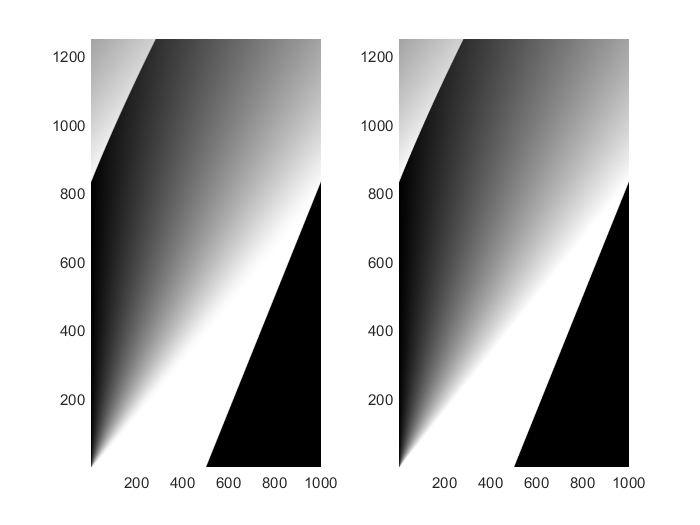


subplot(1,2,2)
surf(sol.','EdgeColor','none');
view(2), axis tight;
colormap gray;




%% Helper functions

function u = BoundaryCorrection(u)
u(1) = u(end-1);
u(end)=u(2);

end

function dt = cflcon(cflcoe, u, dx, t, tf)
dt = cflcoe * dx / max(abs(u));

if((t+dt) > tf)
    dt = tf - t;
end

end

function u = update(u, flux, dt, dx)
u(2:end-1) = u(2:end-1) - dt/dx*diff(flux);

end

function flux = fluxes_MUSCL(U)
% Data reconstruction X
Um1 = circshift(U, 1,1); %i-1
Up1 = circshift(U,-1,1); %i+1

ri = (U-Um1)./(Up1 - U);
ri(isnan(ri))=0;
phii = max(0,min(1,ri)); % minmod limiter

Uxm = U - Um1;
Ux0 = 0.5*(Up1 - Um1);
Uxp = Up1 - U;
Ux = MinModMulti(Uxm,Ux0,Uxp,1.0);

ULL = Um1 + 0.5*circshift(Ux, 1,1);
ULR = U - 0.5*Ux;

%ULL = Um1 + 0.5*circshift(phii, 1,1).*(U - Um1);
%ULR = U   - 0.5*phii.*(Up1 - U);

f = @(u)(0.5.*u.^2);

a = max(abs(ULL),abs(ULR));
Fstar = 0.5*(f(ULR)+f(ULL) - a.*(ULR-ULL));



% Compute Godunov intercell flux
flux = Fstar(2:end);

end

function flux = fluxes_riemann(u)
ul = u(1:end-1);
ur = u(2:end);

% Call riemann solver for inviscid burger
ustar = arrayfun(@riemann,ul,ur);

% Compute Godunov intercell flux
flux = 0.5*ustar.*ustar;

end

function ustar = riemann(ul,ur)
if(ul > ur)
    S = 0.5*(ul+ur);
    
    if(S >= 0.0)
        ustar = ul;
    else
        ustar = ur;
    end
else
    if(ul >= 0.0)
        ustar = ul;
    end
    
    if(ur <= 0.0)
        ustar = ur;
    end
    
    if(ul <= 0.0 && ur >= 0.0)
        ustar = 0.0;
    end
end

end

function d = MinModMulti(a0,a1,a2,theta)
a0 = theta*a0;
a2 = theta*a2;
d = max(max(a0,a1),a2).*(sign(a0)<0);

d = d + min(min(a0,a1),a2).*(sign(a0)>0);

d(sign(a0).*sign(a2)<=0) = 0;

end